# Generate figure 3 of the paper "Choice of trimming proportion and number of clusters in robust clustering based on trimming"  

### Luis A. García-Escudero, Christian Hennig, Agustin Mayo Iscar,  Gianluca Morelli, Marco Riani 

Remark: we assume that you have FSDA installed, at least version 8.7.7.6

In order to install FSDA, in the Home menu click on Add-Ons and search for FSDA.

Xt=readtable('fig3.csv');
X=table2array(Xt);


Restriction factor c=50, 3 groups and no trimming

ClaLik with untrimmed units selected using crisp criterion
Total estimated time to complete tclust:  0.45 seconds 


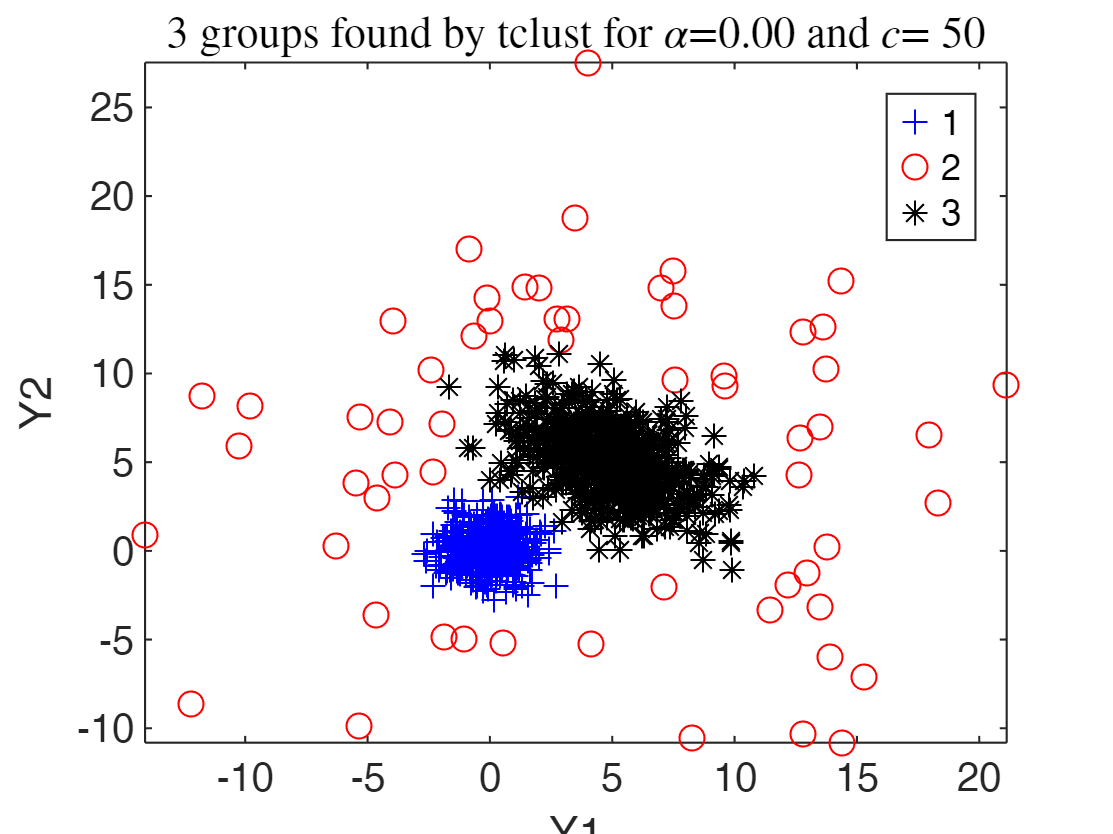

c=50;
k=3;
alpha=0;
try
    out=tclust(X,k,alpha,c,'plots',1,'nsamp',5000);

catch
    error('FSDA:missingFSDA','FSDA toolbox is not installed')
end

Restriction factor c=1, 4 groups and $\alpha$=0.08

ClaLik with untrimmed units selected using crisp criterion
Total estimated time to complete tclust:  6.69 seconds 


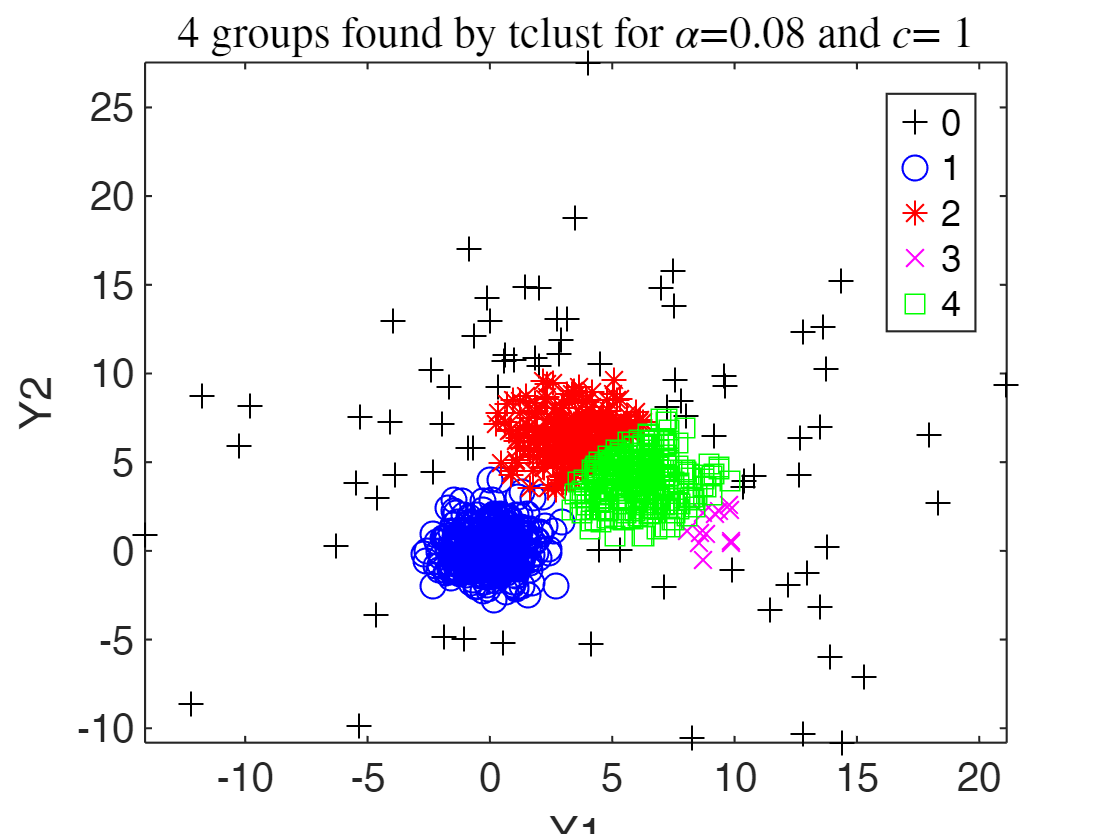

c=1;
k=4;
alpha=0.08;
try
    out1=tclust(X,k,alpha,c,'plots',1,'nsamp',5000);

catch
    error('FSDA:missingFSDA','FSDA toolbox is not installed')
end